# **计算纳米棒成像**

% theta_illum = 64;
% phis = 10:10:360;
% AR = 1.2:0.2:4;
% I = zeros(201, 201, 36, length(AR));
% for ii = 1:length(AR)
%     tic
%     for jj = 1:length(phis)
%         p_rod = FarFieldCalcu('BEM_rod', theta_illum, ...
%             phis(jj), 'AR', AR(ii), 'd', 60, 'mat', 'Ag');
%         p_rod = p_rod.imageCalcu;
%         I(:, :, jj, ii) = power(vecnorm(p_rod.E_image, 2, 3), 2);
%     end
%     figure; imagesc(squeeze(sum(I(:,:,:,ii),3))); 
%     axis equal; axis off
%     title(['AR = ' num2str(AR(ii))]);
%     toc
% end

# **计算不同偏振光照明下颗粒成像**

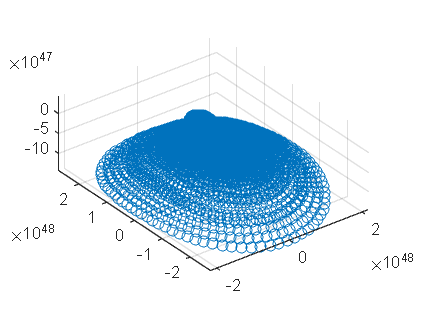

% theta_illum = 64;
% phis = 10:10:360;
% polarization = {'p', 's'};
% I = zeros(25, 25, 36, 2);
% for ii = 1:2
%     tic
%     for jj = 1:length(phis)
%         p_rod = FarFieldCalcu('BEM_rod', theta_illum, ...
%             phis(jj), 'AR', 1, 'd', 60, 'mat', 'Ag', 'polarization', polarization{ii});
%         p_rod = p_rod.imageCalcu;
%         I(:, :, jj, ii) = power(vecnorm(p_rod.E_image, 2, 3), 2);
%     end
%     figure; imagesc(squeeze(sum(I(:,:,:,ii),3))); 
%     axis equal; axis off
%     title(['polarization : ' polarization{ii}]);
%     toc
% end
tic
theta = deg2rad(30);
phis = linspace(0, 2*pi, 9);

for jj = 1:length(phis)-1
    p_rod = FarFieldCalcu('Theory_dipole', [sin(theta)*cos(phis(jj)) sin(theta)*sin(phis(jj)) cos(theta)], 1);
    p_rod = p_rod.imageCalcu;
    colormap(hot)
end

% figure; imagesc(squeeze(abs(p_rod.E_image(:,:,1))));
% axis equal; axis off; colorbar
% title('polarization : x');
% figure; imagesc(squeeze(abs(p_rod.E_image(:,:,2))));
% axis equal; axis off
% title('polarization : y'); colorbar
toc


